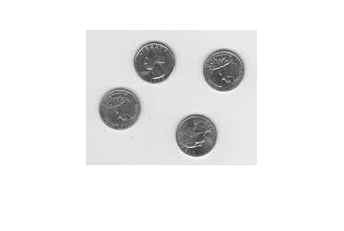

img = rgb2gray(imread('eight.tif'));
imshow(img);

[r,c] = size(img);
weights = [2 2 2 2 4 2 2 2 2];

newImg = uint8(zeros(r,c));
for i = 2:r-1
    for j = 2:c-1
        total = 0;
        count = 0;
        for x = i-1:i+1
            for y = j-1:j+1
                count = count+1;
                total = total+(double(img(x,y))*weights(count));
            end
        end
        newImg(i,j) = total/20;
    end
end

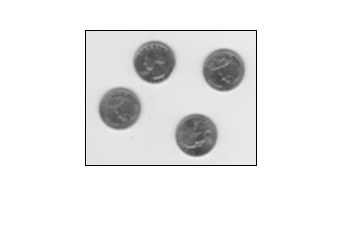

imshow(newImg);